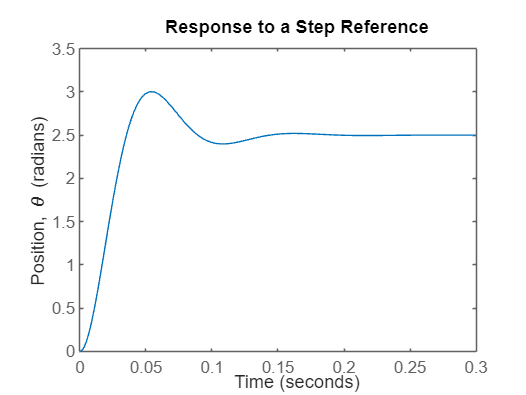

% Simulation of linear system of monocopter with flaps

J = 3.2284E-6; % moment of inertia of the rotor
b = 3.5077E-6; % motor viscous friction constant 
K = 0.0274; % electromotive force constant, motor torque constant 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
H = 1;
stf = servo/(1+(servo*H));
%isstable(stf)
%pole(stf)
%omega_dot_tf = stf; % ndi
omega_dot_tf = stf/(1+(stf*H)); % indi
%sys = feedback(stf,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)

%% to simulate step input of a single servo angle
t = 0:0.001:0.3;
Config = RespConfig('Amplitude',5);
step(omega_dot_tf, t, Config) % step function here is in the form of a servo angle 
ylabel('Position, \theta (radians)')
title('Response to a Step Reference')

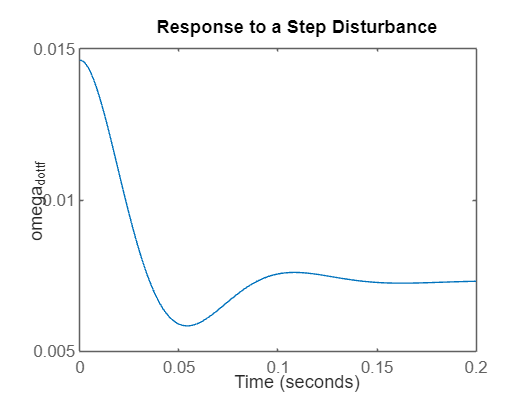

%legend('Kp = 1',  'Kp = 11',  'Kp = 21')


%% to simulate disturbance step input
J = 171;
disturbance_torque_tf = ((1/J)*(1-(H*omega_dot_tf)));
t = 0:0.001:0.2;
Config = RespConfig('Amplitude',5);
step(disturbance_torque_tf, t, Config) % step function here is in the form of a servo angle 
ylabel('omega_dot_tf')
title('Response to a Step Disturbance')